# MIMO GPC - Forma Recursiva

clc; close all; clear all;

#### Constantes

m = 1.79;      g = 9.77412;
Ix = 0.03;     Iy = 0.03;
Iz = 0.04;     T = 0.01;

#### Definición de la planta

G11a = tf(g,[1 0 0]);       % X(s) / Phi(s)
G22a = tf(-g,[1 0 0]);      % Y(s) / Theta(s)

G11b = tf(33.33,[1 0 0]);   % Phi(s) / T_phi(s)
G22b = tf(-33.33,[1 0 0]);  % Theta(s) / T_theta(s)

G11 = G11a * G11b;          % X(s) / T_phi(s)
G22 = G22a * G22b;          % Y(s) / T_theta(s)
G33 = tf(25,[1 0 0]);       % Z(s) / Fz(s)
G44 = tf(0.5587,[1 0 0]);   % Psi(s) / T_psi(s)

% Cambio de variable: como solo tenemos 4 actuadores, solo vamos
% a actuar en 4 variables (x,y,z,psi)

n_in = 4;

Ps = [G11   0    0    0;
       0   G22   0    0;
       0    0   G33   0;
       0    0    0   G44];

Ts = 0.01;                      % Tiempo de muestreo
Pz = c2d(Ps,Ts);                % Proceso discreto

[Bp,Ap,dp] = descompMPC(Pz)     % Descompone num, den y atraso de Pz en celdas

Bp = 4×4 cell array
    {[0 1.3574e-07 1.4931e-06 1.4931e-06 1.3574e-07]}    {[                                            0]}    {[              0]}    {[                      0]}
    {[                                            0]}    {[0 1.3574e-07 1.4931e-06 1.4931e-06 1.3574e-07]}    {[              0]}    {[                      0]}
    {[                                            0]}    {[                                            0]}    {[0 0.0013 0.0013]}    {[                      0]}
    {[                                            0]}    {[                                            0]}    {[              0]}    {[0 2.7935e-05 2.7935e-05]}


Ap = 4×4 cell array
    {[1 -4 6 -4 1]}    {[          1]}    {[     1]}    {[     1]}
    {[          1]}    {[1 -4 6 -4 1]}    {[     1]}    {[     1]}
    {[          1]}    {[          1]}    {[1 -2 1]}    {[     1]}
    {[          1]}    {[          1]}    {[     1]}    {[1 -2 1]}


dp =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


#### Parametros de sintonia del GPC

% Encuentro cual es el retardo minimo en mi función de transferencia
dmin = [0 0 0 0]';
for i=1:n_in
    dmin(i) = min(dp(i,:));
end 

N = [140;140;140;140];                          % Ventana u Horizonte de Predicción
N1 = [dmin(1)+1 dmin(2)+1 dmin(3)+1 dmin(4)+1]; % Horizonte Inicial
N2 = [dmin(1)+N(1) dmin(2)+N(2) dmin(3)+N(3) dmin(4)+N(4)];         % Horizonte final
Nu = [120;120;120;120];                         % Horizonte de control
lambda = [1 1 1 1];                             % Ponderación de la acción de control
delta = [1 1 1 1];                              % Ponderación del seguimiento de referencia

#### Matrices en bloque de los parametros de ponderación

blkdiag(): Función de Matlab que toma cada valor y los ubica en una matriz diagonal

Ql=blkdiag(lambda(1)*eye(Nu(1)), lambda(2)*eye(Nu(2)), ...
           lambda(3)*eye(Nu(3)), lambda(4)*eye(Nu(4)) )  %(lambda -> Acción de Control)

Ql =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0  


Qd=blkdiag(delta(1)*eye(N(1)), delta(2)*eye(N(2)), ...
           delta(3)*eye(N(3)), delta(4)*eye(N(4)) )      %(delta  -> Seguimiento de Referencia)

Qd =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0  

#### Cálculo de la ecuación Diofantina

Se obtiene la matriz $B$ y $A$ (Numerador y denominador sistema MIMO). La matriz $A$ es el minimo común denominador del sistema, es decir, $A_i(z^{-1})$

[Bt,A] = BA_MIMO(Bp,Ap)

Bt = 4×4 cell array
    {[1.3574e-07 1.4931e-06 1.4931e-06 1.3574e-07]}    {[                                  0 0 0 0 0]}    {[    0 0 0 0 0]}    {[            0 0 0 0 0]}
    {[                                  0 0 0 0 0]}    {[1.3574e-07 1.4931e-06 1.4931e-06 1.3574e-07]}    {[    0 0 0 0 0]}    {[            0 0 0 0 0]}
    {[                                      0 0 0]}    {[                                      0 0 0]}    {[0.0013 0.0013]}    {[                0 0 0]}
    {[                                      0 0 0]}    {[                                      0 0 0]}    {[        0 0 0]}    {[2.7935e-05 2.7935e-05]}


A = 4×4 cell array
    {[1 -4 6 -4 1]}    {0×0 double   }    {0×0 double}    {0×0 double}
    {0×0 double   }    {[1 -4 6 -4 1]}    {0×0 double}    {0×0 double}
    {0×0 double   }    {0×0 double   }    {[  1 -2 1]}    {0×0 double}
    {0×0 double   }    {0×0 double   }    {0×0 double}    {[  1 -2 1]}


Cálculo de las Diofantinas para el sistema multivariable

(Ecuación 6.5 Libro)

[E,En,F] = diophantineMIMO(A,N,dmin)

E = 1×4 cell array
    {[1 5 15 35 70 126 210 330 495 715 1001 1365 1820 2380 3060 3876 4845 5985 7315 8855 10626 12650 14950 17550 20475 23751 27405 31465 35960 40920 46376 52360 58905 66045 73815 82251 91390 101270 111930 123410 135751 148995 163185 178365 194580 211876 230300 249900 270725 292825 316251 341055 367290 395010 424270 455126 487635 521855 557845 595665 635376 677040 720720 766480 814385 864501 916895 971635 1028790 1088430 1150626 1215450 1282975 1353275 1426425 1502501 1581580 1663740 1749060 1837620 1929501 2024785 2123555 2225895 2331890 2441626 2555190 2672670 2794155 2919735 3049501 3183545 3321960 3464840 3612280 3764376 3921225 4082925 4249575 4421275 4598126 4780230 4967690 5160610 5359095 5563251 5773185 5989005 6210820 6438740 6672876 6913340 7160245 7413705 7673835 7940751 8214570 8495410 8783390 9078630 9381251 9691375 10009125 10334625 10668000 11009376 11358880 11716640 12082785 12457445 12840751 13232835 13633830 14043870 14463090 14891626 15329615 157771

En = 1×4 cell array
    {140×140 double}    {140×140 double}    {140×140 double}    {140×140 double}


F = 1×4 cell array
    {140×5 double}    {140×5 double}    {140×3 double}    {140×3 double}


Matriz de la Respuesta Forzada $G$

[G] = MatrizG(E,Bt,N,Nu,dp);

Sistema sin Restricciones


$$K=(G^T \; Q_d \; G + Q_l)\; G^T \; Q_d$$


M=inv(G'*Qd*G+Ql)*G'*Qd;    % Ganancia M
K1=M(1,:);                  % Tomo la primera columna unicamente (para control u1)
K2=M(Nu(1)+1,:);            % Tomo valores de M desde [N(1)+1] una muestra despues del primer 
                            % horizonte de control (para control u2)
K3=M(Nu(1)+Nu(2)+1,:);
K4=M(Nu(1)+Nu(2)+Nu(3)+1,:);

#### Señales del processo MIMO 4x4 (Inicialización)

% Inicializa parametros de Simulacion

% Numero de interacciones
nit = 400; 

% Inicializa vector de las respuestas libres
y_free1 = [];
y_free2 = [];
y_free3 = [];
y_free4 = [];

% Inicializa vectores de los incrementos de control
deltaU1(1:nit) = 0;            
deltaU2(1:nit) = 0;
deltaU3(1:nit) = 0;            
deltaU4(1:nit) = 0;

% Salidas de cada bloque MIMO
yp11(1:nit) = 0; 
yp12(1:nit) = 0; 
yp13(1:nit) = 0; 
yp14(1:nit) = 0; 

yp21(1:nit) = 0; 
yp22(1:nit) = 0; 
yp23(1:nit) = 0; 
yp24(1:nit) = 0; 

yp31(1:nit) = 0; 
yp32(1:nit) = 0; 
yp33(1:nit) = 0; 
yp34(1:nit) = 0; 

yp41(1:nit) = 0; 
yp42(1:nit) = 0; 
yp43(1:nit) = 0; 
yp44(1:nit) = 0; 

yp(1:2) = 0;

% Salidas MIMO
y1(1:nit) = 0; 
y2(1:nit) = 0; 
y3(1:nit) = 0; 
y4(1:nit) = 0; 

% Referencias
r1(10:nit) = 0.5; 
r2(40:nit) = 0.25;
r3(80:nit) = 0.5; 
r4(120:nit) = 0.25; 

% Acciones de Control
u1(1:nit) = 0; 
u2(1:nit) = 0;
u3(1:nit) = 0; 
u4(1:nit) = 0; 

%% Hasta aquí voy con el Libro
% Atil (Producto entre polinomio A y el integrador)
At{1,1}=conv(A{1,1},[1 -1]); % (z-1)
At{2,2}=conv(A{2,2},[1 -1]);
At{3,3}=conv(A{3,3},[1 -1]);
At{4,4}=conv(A{3,3},[1 -1]);

% Se determina el tamaño de cada polinomio Atil
na1=length(At{1,1})-1;                    
na2=length(At{2,2})-1;  
na3=length(At{3,3})-1;                       
na4=length(At{4,4})-1; 

% Se determina el tamaño de cada polinomio B proveniente del calculo del minimo
% común denominador de la funcion "BA_MIMO"
nb1_11=length(Bt{1,1});                       
nb1_21=length(Bt{2,1});
nb1_31=length(Bt{3,1});                       
nb1_41=length(Bt{4,1});

nb1_12=length(Bt{1,2});                       
nb1_22=length(Bt{2,2});   
nb1_32=length(Bt{3,2});                       
nb1_42=length(Bt{4,2}); 

nb1_13=length(Bt{1,3});                       
nb1_23=length(Bt{2,3});   
nb1_33=length(Bt{3,3});                       
nb1_43=length(Bt{4,3}); 

nb1_14=length(Bt{1,4});                       
nb1_24=length(Bt{2,4});   
nb1_34=length(Bt{3,4});                       
nb1_44=length(Bt{4,4});

#### Inicio del Lazo de Control

for k=10:nit       
    t = 0:Ts:(k-1)*Ts;
    yest=lsim(Ps,[u1(1:k);u2(1:k);u3(1:k);u4(1:k)],t,'zoh');
    y1(k)=yest(end,1);
    y2(k)=yest(end,2);
    y3(k)=yest(end,3);
    y4(k)=yest(end,4);

#### Vectores que conforman la Respuesta Libre

Creo el vector de controles pasados basandome en la ecuación de salida del modelo de la planta actual $y(k)$. Osea, coloco en un vector todos los incrementos de control de cada una de las entradas, algo como:

[deltaU(k-1) deltaU(k-2) ... deltaU(k-nb)] donde "nb" es la longitud del vector B (Numerador del modelo)

      % Controles pasados de y1 en el instante actual
      deltaU11_pas=deltaU1(k-dp(1,1)-1:-1:k-dp(1,1)-nb1_11);           
      deltaU12_pas=deltaU2(k-dp(1,2)-1:-1:k-dp(1,2)-nb1_12); 
      deltaU13_pas=deltaU3(k-dp(1,3)-1:-1:k-dp(1,3)-nb1_13);           
      deltaU14_pas=deltaU4(k-dp(1,4)-1:-1:k-dp(1,4)-nb1_14); 

      % Controles pasados de y2 en el instante actual
      deltaU21_pas=deltaU1(k-dp(2,1)-1:-1:k-dp(2,1)-nb1_21);           
      deltaU22_pas=deltaU2(k-dp(2,2)-1:-1:k-dp(2,2)-nb1_22); 
      deltaU23_pas=deltaU3(k-dp(2,3)-1:-1:k-dp(2,3)-nb1_23);           
      deltaU24_pas=deltaU4(k-dp(2,4)-1:-1:k-dp(2,4)-nb1_24); 

      % Controles pasados de y3 en el instante actual
      deltaU31_pas=deltaU1(k-dp(3,1)-1:-1:k-dp(3,1)-nb1_31);           
      deltaU32_pas=deltaU2(k-dp(3,2)-1:-1:k-dp(3,2)-nb1_32); 
      deltaU33_pas=deltaU3(k-dp(3,3)-1:-1:k-dp(3,3)-nb1_33);           
      deltaU34_pas=deltaU4(k-dp(3,4)-1:-1:k-dp(3,4)-nb1_34); 

      % Controles pasados de y4 en el instante actual
      deltaU41_pas=deltaU1(k-dp(4,1)-1:-1:k-dp(4,1)-nb1_41);           
      deltaU42_pas=deltaU2(k-dp(4,2)-1:-1:k-dp(4,2)-nb1_42); 
      deltaU43_pas=deltaU3(k-dp(4,3)-1:-1:k-dp(4,3)-nb1_43);           
      deltaU44_pas=deltaU4(k-dp(4,4)-1:-1:k-dp(4,4)-nb1_44); 
      

Creo un vector de salidas pasadas, similar al vector de controles pasados solo que en este caso con las salidas hasta la longitud del polinomio $A$ (denominador del modelo)

      y_pas1=y1(k:-1:k-na1+1);                         % Vector de salida
      y_pas2=y2(k:-1:k-na2+1);                         % Vector de salida
      y_pas3=y3(k:-1:k-na3+1);                         % Vector de salida
      y_pas4=y4(k:-1:k-na4+1);                         % Vector de salid3

#### Predicciones hasta el horizonte de predicción $N_2$

Comienzo a desplazar los $\Delta u$ pasados a medida que aumenta la ventana de predicción, hasta que la predicción en este vector llegue al retardo.

Una vez la ventana de predicción es mayor que el retardo, en la ecuación de salida dejan de existir los $\Delta u$ pasados y comenzaran a aparecer los $\Delta u$ futuros, por eso comienzo a cerar los $\Delta u$ pasados.

      n=1; %Indice para la salida libre
      for j=1:N2(1)
          
          if j<=dp(1,1) 
              deltaU11_pas=[deltaU1(k-dp(1,1)-1+j) deltaU11_pas(1:end-1)];
          elseif j>dp(1,1) 
              deltaU11_pas=[0 deltaU11_pas(1:end-1)];
          end

          if j<=dp(1,2) 
              deltaU12_pas=[deltaU2(k-dp(1,2)-1+j) deltaU12_pas(1:end-1)];
          elseif j>dp(1,2) 
              deltaU12_pas=[0 deltaU12_pas(1:end-1)];
          end

          if j<=dp(1,3) 
              deltaU13_pas=[deltaU3(k-dp(1,3)-1+j) deltaU13_pas(1:end-1)];
          elseif j>dp(1,3) 
              deltaU13_pas=[0 deltaU13_pas(1:end-1)];
          end  

          if j<=dp(1,4) 
              deltaU14_pas=[deltaU4(k-dp(1,4)-1+j) deltaU14_pas(1:end-1)];
          elseif j>dp(1,4) 
              deltaU14_pas=[0 deltaU14_pas(1:end-1)];
          end             


$$A_i(z^{-1})\;y_i(t)=z^{-d_i}\;B_i(z^{-1})\;u(t-1)+\frac{1}{\Delta}e(t)$$


Se realiza el cálculo de la respuesta libre con el polinomio $Atil$ y el polinomio $B$, junto con las salidas pasadas y los $\Delta u$ pasados

          y_free1(n)=-y_pas1*At{1,1}(2:end)' + deltaU11_pas*Bt{1,1}(1:end)'...
                                             + deltaU12_pas*Bt{1,2}(1:end)'...
                                             + deltaU13_pas*Bt{1,3}(1:end)'...
                                             + deltaU14_pas*Bt{1,4}(1:end)';% Armazena yfr
          
          % Actualizo el vector de salidas pasadas
          y_pas1=[y_free1(n) y_pas1(1:end-1)];         
          n=n+1;
      end

Predicciones hasta el horizonte de predicción

      n=1; %Indice para la salida libre
      for j=1:N2(2)
          
          if j<=dp(2,1)
              deltaU21_pas=[deltaU1(k-dp(2,1)-1+j) deltaU21_pas(1:end-1)];
          elseif j>dp(2,1)
              deltaU21_pas=[0 deltaU21_pas(1:end-1)];
          end

          if j<=dp(2,2)
              deltaU22_pas=[deltaU2(k-dp(2,2)-1+j) deltaU22_pas(1:end-1)];
          elseif j>dp(2,2)
              deltaU22_pas=[0 deltaU22_pas(1:end-1)];
          end

          if j<=dp(2,3)
              deltaU23_pas=[deltaU3(k-dp(2,3)-1+j) deltaU23_pas(1:end-1)];
          elseif j>dp(3,2)
              deltaU23_pas=[0 deltaU23_pas(1:end-1)];
          end   

          if j<=dp(2,4)
              deltaU24_pas=[deltaU4(k-dp(2,4)-1+j) deltaU24_pas(1:end-1)];
          elseif j>dp(4,2)
              deltaU24_pas=[0 deltaU24_pas(1:end-1)];
          end

          y_free2(n)=-y_pas2*At{2,2}(2:end)' + deltaU21_pas*Bt{2,1}(1:end)'...
                                             + deltaU22_pas*Bt{2,2}(1:end)' ...
                                             + deltaU23_pas*Bt{2,3}(1:end)' ...
                                             + deltaU24_pas*Bt{2,4}(1:end)';% Armazena yfr
          
          % Actualizo el vector de salidas pasadas
          y_pas2=[y_free2(n) y_pas2(1:end-1)];                    % Actualiza yfr
          n=n+1;
      end

      n=1; % Indice para la salida libre
      for j=1:N2(3)
          
          if j<=dp(3,1)
              deltaU31_pas=[deltaU1(k-dp(3,1)-1+j) deltaU31_pas(1:end-1)];
          elseif j>dp(3,1)
              deltaU31_pas=[0 deltaU31_pas(1:end-1)];
          end

          if j<=dp(3,2)
              deltaU32_pas=[deltaU2(k-dp(3,2)-1+j) deltaU32_pas(1:end-1)];
          elseif j>dp(3,2)
              deltaU32_pas=[0 deltaU32_pas(1:end-1)];
          end

          if j<=dp(3,3)
              deltaU33_pas=[deltaU3(k-dp(3,3)-1+j) deltaU33_pas(1:end-1)];
          elseif j>dp(3,3)
              deltaU33_pas=[0 deltaU33_pas(1:end-1)];
          end   
          
          if j<=dp(3,4)
              deltaU34_pas=[deltaU4(k-dp(3,4)-1+j) deltaU34_pas(1:end-1)];
          elseif j>dp(3,4)
              deltaU34_pas=[0 deltaU34_pas(1:end-1)];
          end

          y_free3(n)=-y_pas3*At{3,3}(2:end)' + deltaU31_pas*Bt{3,1}(1:end)'...
                                             + deltaU32_pas*Bt{3,2}(1:end)' ...
                                             + deltaU33_pas*Bt{3,3}(1:end)' ...
                                             + deltaU34_pas*Bt{3,4}(1:end)';% Armazena yfr
          
          % Actualizo el vector de salidas pasadas
          y_pas3=[y_free3(n) y_pas3(1:end-1)];                    % Actualiza yfr
          n=n+1;
      end

      n=1; % Indice para la salida libre
      for j=1:N2(4)

          if j<=dp(4,1)
              deltaU41_pas=[deltaU1(k-dp(4,1)-1+j) deltaU41_pas(1:end-1)];
          elseif j>dp(4,1)
              deltaU41_pas=[0 deltaU41_pas(1:end-1)];
          end

          if j<=dp(4,2)
              deltaU42_pas=[deltaU2(k-dp(4,2)-1+j) deltaU42_pas(1:end-1)];
          elseif j>dp(4,2)
              deltaU42_pas=[0 deltaU42_pas(1:end-1)];
          end

          if j<=dp(4,3)
              deltaU43_pas=[deltaU3(k-dp(4,3)-1+j) deltaU43_pas(1:end-1)];
          elseif j>dp(4,3)
              deltaU43_pas=[0 deltaU43_pas(1:end-1)];
          end 

          if j<=dp(4,4)
              deltaU44_pas=[deltaU4(k-dp(4,4)-1+j) deltaU44_pas(1:end-1)];
          elseif j>dp(4,4)
              deltaU44_pas=[0 deltaU44_pas(1:end-1)];
          end

          y_free4(n)=-y_pas4*At{4,4}(2:end)' + deltaU41_pas*Bt{4,1}(1:end)'...
                                             + deltaU42_pas*Bt{4,2}(1:end)' ...
                                             + deltaU43_pas*Bt{4,3}(1:end)' ...
                                             + deltaU44_pas*Bt{4,4}(1:end)';% Armazena yfr
          
          % Actualizo el vector de salidas pasadas
          y_pas4=[y_free4(n) y_pas4(1:end-1)];                    % Actualiza yfr
          n=n+1;
      end

#### Cálculo del Incremento de Control   

Cálculo los incrementos de control utilizando unicamente los datos de las** respuestas libres **que se encuentran dentro de los horizontes de predicción $N_1$ y $N_2$, y se hace el producto con la ganancia calculada de la **respuesta forzada**.

% Qué es respuesta libre y forzada

    deltaU1(k)=K1*[(r1(k)*ones(1,length(y_free1(N1(1):N2(1))))' - y_free1(N1(1):N2(1))');
                   (r2(k)*ones(1,length(y_free2(N1(2):N2(2))))' - y_free2(N1(2):N2(2))');
                   (r3(k)*ones(1,length(y_free3(N1(3):N2(3))))' - y_free3(N1(3):N2(3))');
                   (r4(k)*ones(1,length(y_free4(N1(4):N2(4))))' - y_free4(N1(4):N2(4))')];

    deltaU2(k)=K2*[(r1(k)*ones(1,length(y_free1(N1(1):N2(1))))' - y_free1(N1(1):N2(1))');
                   (r2(k)*ones(1,length(y_free2(N1(2):N2(2))))' - y_free2(N1(2):N2(2))');
                   (r3(k)*ones(1,length(y_free3(N1(3):N2(3))))' - y_free3(N1(3):N2(3))');
                   (r4(k)*ones(1,length(y_free4(N1(4):N2(4))))' - y_free4(N1(4):N2(4))')];

    deltaU3(k)=K3*[(r1(k)*ones(1,length(y_free1(N1(1):N2(1))))' - y_free1(N1(1):N2(1))');
                   (r2(k)*ones(1,length(y_free2(N1(2):N2(2))))' - y_free2(N1(2):N2(2))');
                   (r3(k)*ones(1,length(y_free3(N1(3):N2(3))))' - y_free3(N1(3):N2(3))');
                   (r4(k)*ones(1,length(y_free4(N1(4):N2(4))))' - y_free4(N1(4):N2(4))')];

    deltaU4(k)=K4*[(r1(k)*ones(1,length(y_free1(N1(1):N2(1))))' - y_free1(N1(1):N2(1))');
                   (r2(k)*ones(1,length(y_free2(N1(2):N2(2))))' - y_free2(N1(2):N2(2))');
                   (r3(k)*ones(1,length(y_free3(N1(3):N2(3))))' - y_free3(N1(3):N2(3))');
                   (r4(k)*ones(1,length(y_free4(N1(4):N2(4))))' - y_free4(N1(4):N2(4))')];

#### Cálculo la acción de Control


$$u_i(k)=u_i(k-1) + \Delta u_i(k)$$


     if k==1
        u1(k)=deltaU1(k);
        u2(k)=deltaU2(k);
        u3(k)=deltaU3(k);
        u4(k)=deltaU4(k);
     else
        u1(k)=u1(k-1) + deltaU1(k);
        u2(k)=u2(k-1) + deltaU2(k);
        u3(k)=u3(k-1) + deltaU3(k);
        u4(k)=u4(k-1) + deltaU4(k);
     end
     
end

#### Gráfico los Resultados

nm=nit;
t = 0:Ts:(nit-1)*Ts;

figure
subplot(2,1,1)
plot(t,r1,t,r2,t,y1,t,y2,'Linewidth',1)
title('Respuesta al Escalón')
xlabel('Tiempo (s)');
ylabel('Salida');
legend('r1(t)','r2(t)','y1(t)','y2(t)')
grid on;
hold

Current plot held


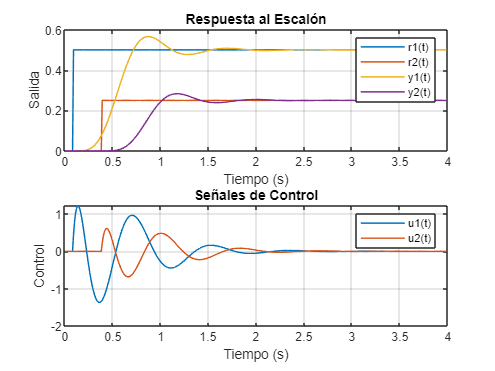


subplot(2,1,2)
plot(t,u1,t,u2,'Linewidth',1)
title('Señales de Control')
xlabel('Tiempo (s)');
ylabel('Control');
legend('u1(t)','u2(t)')
grid on;


figure
subplot(2,1,1)
plot(t,r3,t,r4,t,y3,t,y4,'Linewidth',1)
title('Respuesta al Escalón')
xlabel('Tiempo (s)');
ylabel('Salida');
legend('r3(t)','r4(t)','y3(t)','y4(t)')
grid on;
hold

Current plot held


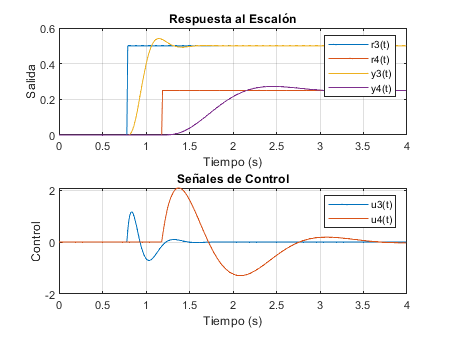


subplot(2,1,2)
plot(t,u3,t,u4,'Linewidth',1)
title('Señales de Control')
xlabel('Tiempo (s)');
ylabel('Control');
legend('u3(t)','u4(t)')
grid on;

#### Notas:

Modificar los pesos del vector lambda, modifica las oscilaciones.

Agregar las restricciones tiene la limitante de que si las queremos incluirlas tenemos que encontrar la forma de representar la respuesta al impulso de las ft con algo que me permita que sea inestable. Nuestra limitante es que es inestable.

Argumentar el por qué NO hacerlo con restricciones, podría ser un trabajo futuro

% Parte conceptual No ahondar mucho en las restricciones Ahondar en trabahjos futuros